load F0000CH1.csv

Error using load
Unable to read file 'F0000CH1.csv'. Input must be a MAT-file or an ASCII file containing numeric data with same number of columns in each row.

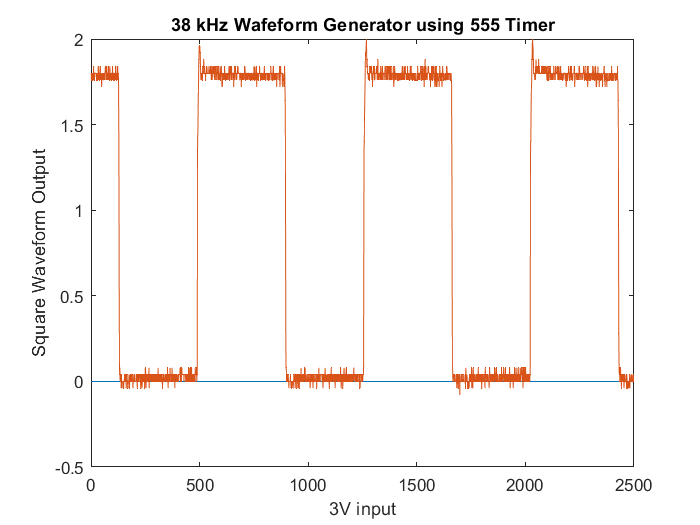

y=F0000CH1;
plot(y)

title("38 kHz Wafeform Generator using 555 Timer")
xlabel("3V input")
ylabel("Square Waveform Output")


freq=meanfreq(y)

freq =     0.0126    0.0112


ft=fftshift(abs(fft(y)))

ft = 	1.0e+03 *

    0.0009    0.0000
    0.0023    0.0000
    0.0015    0.0000
    0.0007    0.0000
    0.0022    0.0000
    0.0013    0.0000
    0.0008    0.0000
    0.0013    0.0000
    0.0006    0.0000
    0.0022    0.0000


figure
time=linspace(0,2500/38000,length(ft))

time =          0    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013


plot(time,ft)

% Find local maxima
peak = islocalmax(ft,'MaxNumExtrema',1,'SamplePoints',time);

idx=find(peak==1)

idx =         1251
        3750



peakk=time(idx(1))

peakk = 0.0329

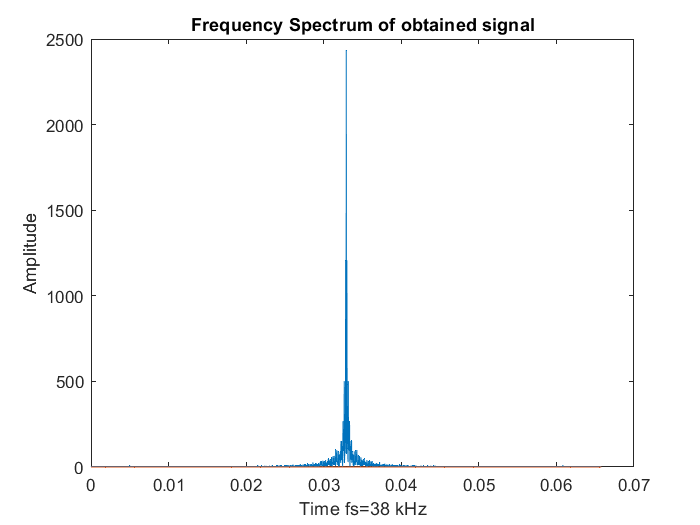


frequency=1/peakk;

title("Frequency Spectrum of obtained signal")
xlabel('Time fs=38 kHz')
ylabel("Amplitude")